# File Consolidation Data

clc, clear;

%Change directory
cd 'C:\Users\HP\OneDrive\Escritorio\MIE_2023\Econometría 2\Trabajo 2025';

%Predetermined
addpath('C:\Users\HP\OneDrive\Escritorio\MIE_2023\Econometría 2\Trabajo 2025');

## 1.Data Consolidation

#### 1.1. Input Yield Variables p1

clc, clear
cd 'C:\Users\HP\OneDrive\Escritorio\MIE_2023\Econometría 2'\'Trabajo 2025'
filename = 'GS_Consol_Int.xlsx';
yields = readtable(filename);

#### 1.1. Input Yield Variables p2

%We select data from november 2005 to may 2025
%Standaring yields vector
%We select 3m, 6m, 1y, 2y, 5y, 7y, 10y, 14y
yields_std = [yields.GS3m yields.GS6m yields.GS1y yields.GS2y yields.GS3y yields.GS5y yields.GS7y yields.GS9y yields.GS10y yields.GS14y];
Date = yields.Date(1:235,:);
yields_std=yields_std(1:235,:);


## Some plots

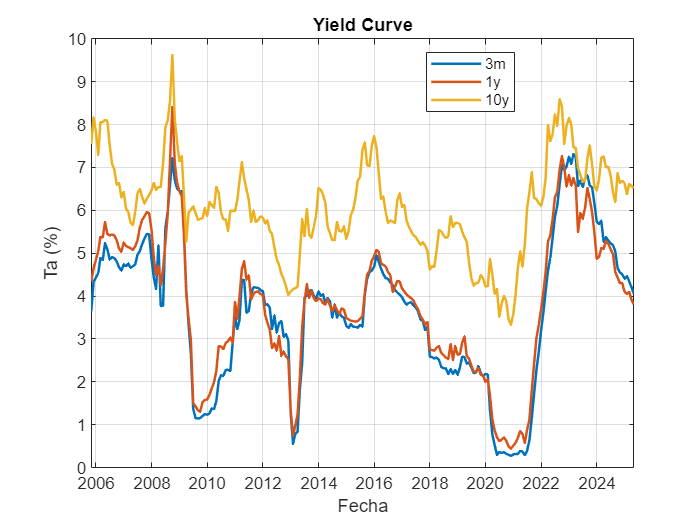

figure;
plot(Date, yields_std(:,1), 'LineWidth', 1.5); hold on; %3m
plot(Date, yields_std(:,3), 'LineWidth', 1.5); hold on; %1y
plot(Date, yields_std(:,8), 'LineWidth', 1.5); hold on; %10y
hold off;

title('Yield Curve');
xlabel('Fecha');
ylabel('Ta (%)');
legend('3m', '1y', '10y', 'Location', 'best');
grid on;

## 1.2. Macro Variables File Calling

filename = 'Macro_Data_Consolidated.xlsx';
macro_vars = readtable(filename);

## 1.2. Macro Variables Data

%Data from November 2005 to May 2025
%1st Group: Inflation
%IPCALI: CPI Food, IPCIMP: CPI Imports, IPCGEN: CPI General
Infl_Meas = [macro_vars.IPCALI macro_vars.IPCIMP macro_vars.IPCGEN];
Infl_Meas = Infl_Meas(55:end,:);


## Some plots

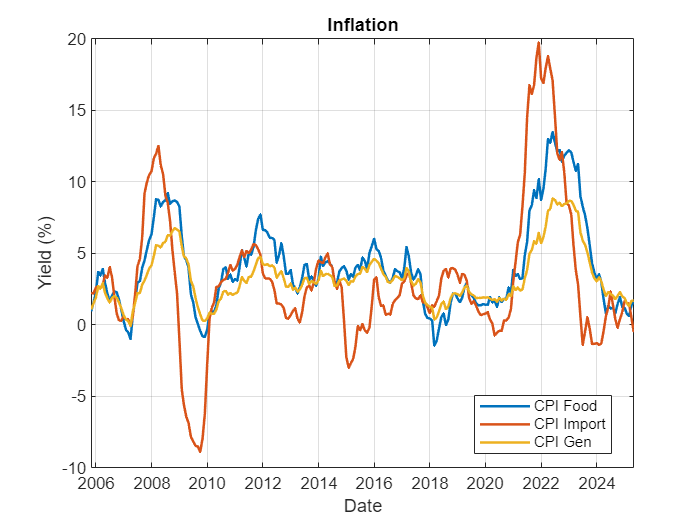

figure;
plot(Date, Infl_Meas (:,1), 'LineWidth', 1.5); hold on;
plot(Date, Infl_Meas (:,2), 'LineWidth', 1.5); hold on;
plot(Date, Infl_Meas (:,3), 'LineWidth', 1.5); hold on;
hold off;

title('Inflation');
xlabel('Date');
ylabel('Yield (%)');
legend('CPI Food', 'CPI Import', 'CPI Gen', 'Location', 'best');
grid on;

## 2nd Group: Real Act

%DEMPLEO: Unemployment, PBIPRIM: GDP Primary, PBINOP: GDP Non Prim
Real_Act_Meas = [[0;-diff(macro_vars.DEMPLEO)] macro_vars.PBIPRIM macro_vars.PBINOP];
Real_Act_Meas = Real_Act_Meas(55:end,:);


## RA plots

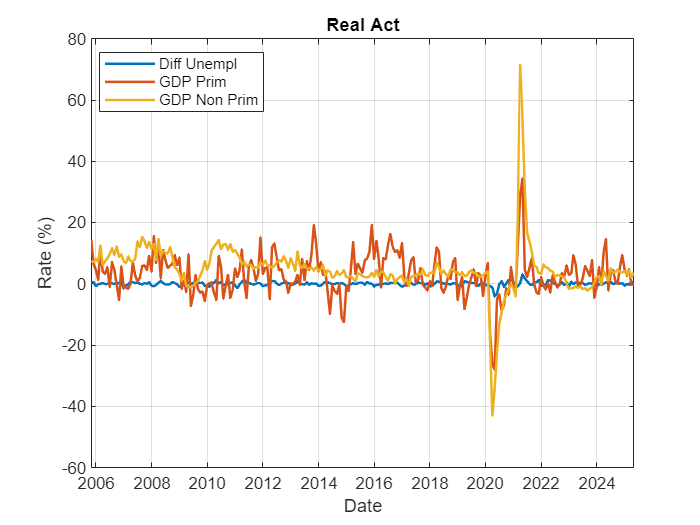

figure;
plot(Date, Real_Act_Meas(:,1), 'LineWidth', 1.5); hold on;
plot(Date, Real_Act_Meas(:,2), 'LineWidth', 1.5); hold on;
plot(Date, Real_Act_Meas(:,3), 'LineWidth', 1.5); hold on;
hold off;

title('Real Act');
xlabel('Date');
ylabel('Rate (%)');
legend('Diff Unempl', 'GDP Prim', 'GDP Non Prim', 'Location', 'best');
grid on;

## 2. Stats

## 2.1. Yields Stats

%3m, 6m, 1y, 2y, 5y, 7y, 10y, 14y
Mean_yields_data = mean(yields_std);
Std_yields_data = std(yields_std);
Skw_yields_data = skewness(yields_std);
Kurtosis_yields_data = kurtosis(yields_std);

%Stats summary on yields
Stats_yields = [Mean_yields_data' Std_yields_data' Skw_yields_data' Kurtosis_yields_data']; 

%Autocorrelation
Autocorr_y_3m = autocorr(yields_std(:,1),'NumLags', 3);
Autocorr_y_6m = autocorr(yields_std(:,2),'NumLags', 3);
Autocorr_y_1y = autocorr(yields_std(:,3),'NumLags', 3);
Autocorr_y_2y = autocorr(yields_std(:,4),'NumLags', 3);
Autocorr_y_5y = autocorr(yields_std(:,5),'NumLags', 3);
Autocorr_y_7y = autocorr(yields_std(:,6),'NumLags', 3);
Autocorr_y_10y = autocorr(yields_std(:,7),'NumLags', 3);
Autocorr_y_14y = autocorr(yields_std(:,8),'NumLags', 3);

Autocorr_yields = [Autocorr_y_3m'; Autocorr_y_6m'; Autocorr_y_1y'; Autocorr_y_2y'; Autocorr_y_5y';Autocorr_y_7y'; Autocorr_y_10y'; Autocorr_y_14y'];

%Stats and Correlation plot
Stats_yields;
Autocorr_yields;

## 2.2. Yields Correlations Plot

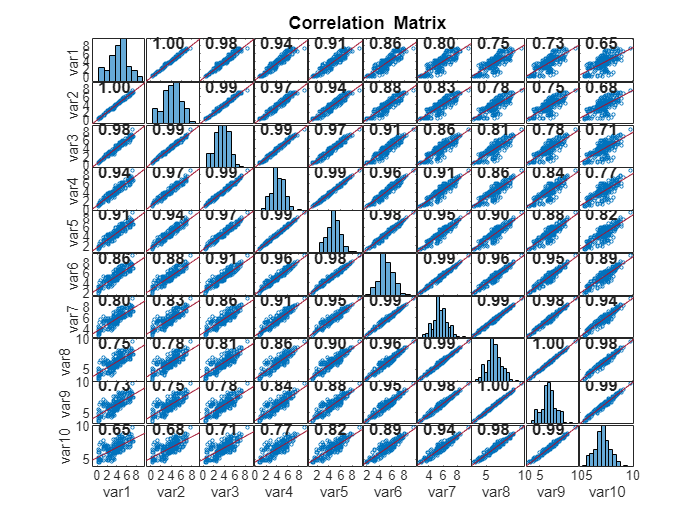

corrplot(yields_std);

## ***2.2. Stats of Yield Treatment to Consider after Stats

%Given high correlation of 3m and 6m. The 6m is not considered and not 5y
%Activated after the correlation review
yields_std=yields_std(:,[1 3 4 7 8 9]); 

%3m 1y, 2y, 5y, 7y, 10y, 14y
Mean_yields_data = mean(yields_std);
Std_yields_data = std(yields_std);
Skw_yields_data = skewness(yields_std);
Kurtosis_yields_data = kurtosis(yields_std);

%Stats summary on yields
Stats_yields = [Mean_yields_data' Std_yields_data' Skw_yields_data' Kurtosis_yields_data']; 

%Autocorrelation
Autocorr_y_3m = autocorr(yields_std(:,1),'NumLags', 3);
Autocorr_y_1y = autocorr(yields_std(:,2),'NumLags', 3);
Autocorr_y_2y = autocorr(yields_std(:,3),'NumLags', 3);
Autocorr_y_7y = autocorr(yields_std(:,4),'NumLags', 3);
Autocorr_y_9y = autocorr(yields_std(:,5),'NumLags', 3);
Autocorr_y_10y = autocorr(yields_std(:,6),'NumLags', 3);

%Autocorr Consolidated
Autocorr_yields = [Autocorr_y_3m'; Autocorr_y_1y'; Autocorr_y_2y';Autocorr_y_7y'; Autocorr_y_9y'; Autocorr_y_10y'];

%Stats and Correlation plot
Stats_yields

Stats_yields =     3.6699    1.7280   -0.1040    2.5571
    3.8183    1.6342   -0.0908    2.5992
    4.1631    1.5533   -0.0194    2.7742
    5.6941    1.2200    0.0619    3.0068
    6.0719    1.1285    0.0488    2.9547
    6.2231    1.0917    0.0417    2.9160


Autocorr_yields

Autocorr_yields =     1.0000    0.9758    0.9360    0.8882
    1.0000    0.9746    0.9310    0.8749
    1.0000    0.9687    0.9222    0.8638
    1.0000    0.9520    0.8899    0.8267
    1.0000    0.9435    0.8732    0.8073
    1.0000    0.9390    0.8649    0.7979


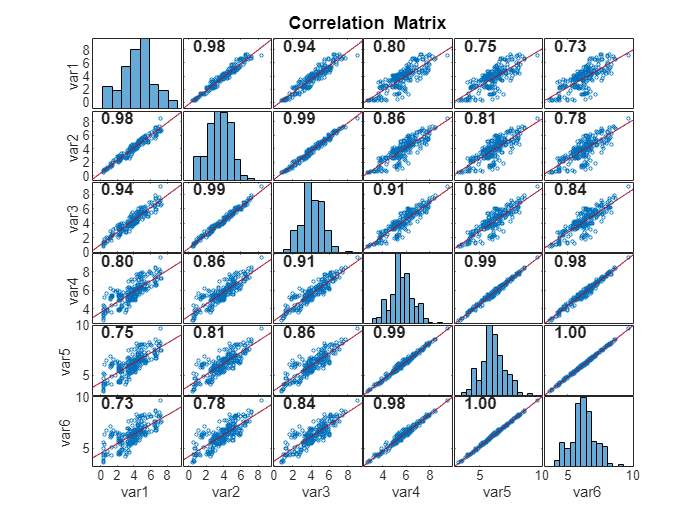

corrplot(yields_std);

## 2.3. Macro Variable Stats

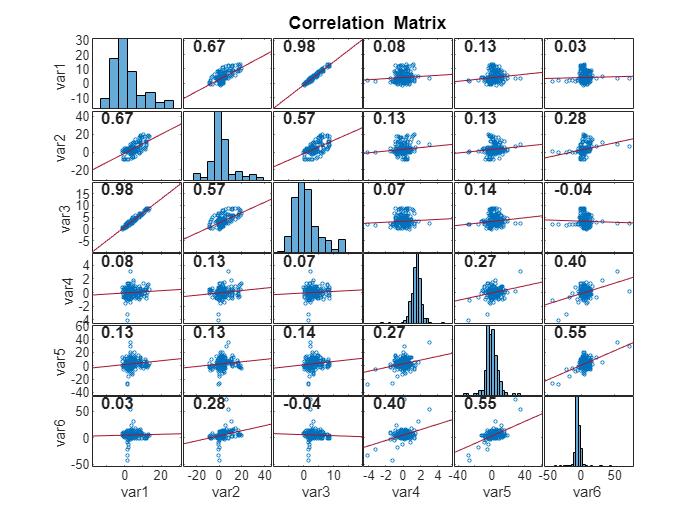

%Economic Indicators
Econ_Ind = [Infl_Meas Real_Act_Meas];
%IPCALI: CPI Food, IPCIMP: CPI Imports, IPCGEN: CPI General
%DEMPLEO: Unemployment, PBIPRIM: GDP Primary, PBINOP: GDP Non Prim
Mean_Econ_data = mean(Econ_Ind);
Std_Econ_data = std(Econ_Ind);
Skw_Econ_data = skewness(Econ_Ind);
Kurtosis_Econ_data = kurtosis(Econ_Ind);
Stats_Econ = [Mean_Econ_data' Std_Econ_data' Skw_Econ_data' Kurtosis_Econ_data'];

%Autocorr
Autocorr_IPCALI = autocorr(Econ_Ind(:,1),'NumLags', 3);
Autocorr_IPCIMP = autocorr(Econ_Ind(:,2),'NumLags', 3);
Autocorr_IPCGEN = autocorr(Econ_Ind(:,3),'NumLags', 3);
Autocorr_DEMPLEO = autocorr(Econ_Ind(:,4),'NumLags', 3);
Autocorr_PBIPRIM = autocorr(Econ_Ind(:,5),'NumLags', 3);
Autocorr_PBINOP = autocorr(Econ_Ind(:,6),'NumLags', 3);

Autocorr_macro = [Autocorr_IPCALI'; Autocorr_IPCIMP'; Autocorr_IPCGEN'; Autocorr_DEMPLEO'; Autocorr_PBIPRIM';Autocorr_PBINOP'];

%Correl plot
corrplot(Econ_Ind);

## 3. Data Treatment

### 3.1. PCA without COVID

[coeff_Infl, score_Infl, latent_Infl] = pca(zscore(Infl_Meas));
infl_activity_factor = score_Infl(:,1); %Factor 1

[coeff_Real, score_Real, latent_Real] = pca(zscore(Real_Act_Meas));
real_activity_factor = score_Real(:,1); %Factor 1

Econ_Factor = [infl_activity_factor real_activity_factor];


## Some plots

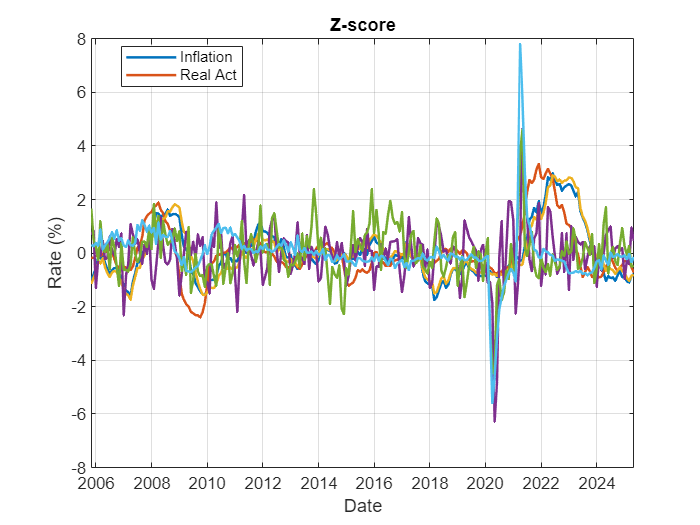

figure;
plot(Date, zscore(Infl_Meas), 'LineWidth', 1.5); hold on;
plot(Date, zscore(Real_Act_Meas), 'LineWidth', 1.5); hold on;
hold off;

title('Z-score');
xlabel('Date');
ylabel('Rate (%)');
legend('Inflation', 'Real Act', 'Location', 'best');
grid on;

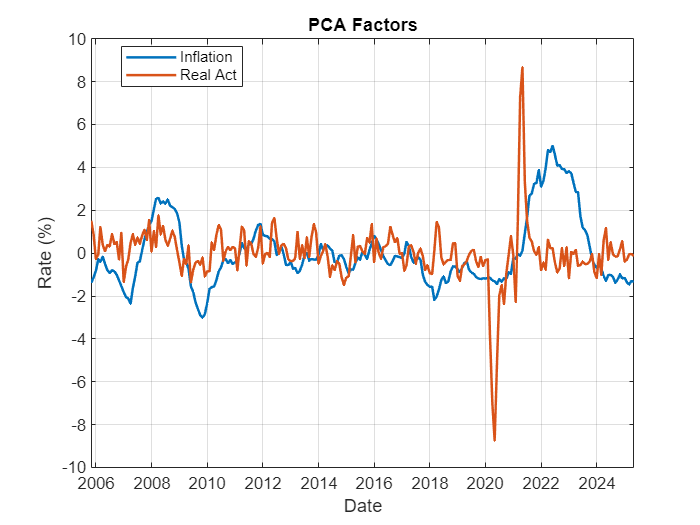

figure;
plot(Date, Econ_Factor(:,1), 'LineWidth', 1.5); hold on;
plot(Date, Econ_Factor(:,2), 'LineWidth', 1.5); hold on;
hold off;

title('PCA Factors');
xlabel('Date');
ylabel('Rate (%)');
legend('Inflation', 'Real Act', 'Location', 'best');
grid on;

### 3.2. PCA with COVID Adjustment

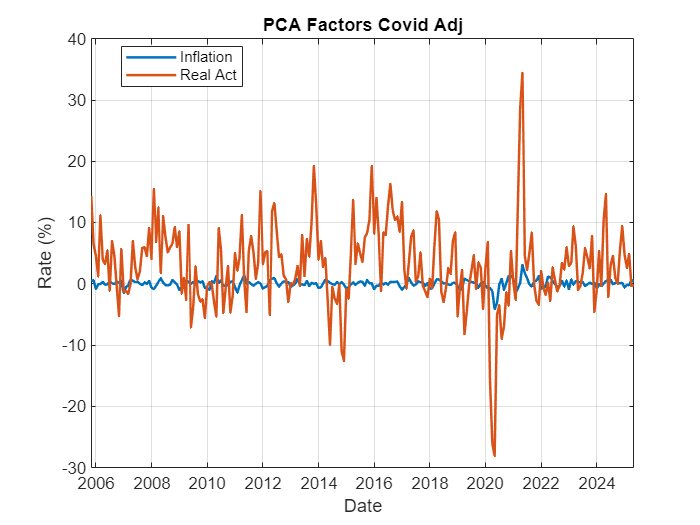

%Precovid dates
baseIdx = Date < datetime(2020,3,1);           % training window

%Inflation
%[Z_Infl,loc_Infl,scale_Infl] = robust_z(Infl_Meas, 'BaseIdx', baseIdx, 'Clip', 6);
[coeff_Infl, score_Infl, latent_Infl] = pca(zscore(Infl_Meas));
infl_activity_factor_adj = score_Infl(:,1);

%Real Activity
[Z_Real,loc_Real,scale_Real] = robust_z(Real_Act_Meas, 'BaseIdx', baseIdx, 'Clip', 6);
[coeff_Real, score_Real, latent_Real] = pca(Z_Real);
real_activity_factor_adj = score_Real(:,1);

Econ_Factor_Adj = [infl_activity_factor_adj real_activity_factor_adj];

figure;
plot(Date, Real_Act_Meas(:,1), 'LineWidth', 1.5); hold on;
plot(Date, Real_Act_Meas(:,2), 'LineWidth', 1.5); hold on;
hold off;

title('PCA Factors Covid Adj');
xlabel('Date');
ylabel('Rate (%)');
legend('Inflation', 'Real Act', 'Location', 'best');
grid on;

## 4. Relationship between Macro Factos: VAR (8) Estimation of Infl and Real Act 

% Given the PCA factor, without the covid adjuntment in the zscore: 
% Then we use the Econ_Factor
%We do 9, given the high noise of teh Ang and Piazzezi 12 lags

p = 8; % # of lags
Mdl  = varm(2,p);
[EstMdl_F_activity,~,~,info] = estimate(Mdl, Econ_Factor, 'Y0', Econ_Factor(1:p,:));  % provide presample

% VAR Summary
summarize(EstMdl_F_activity)

 
   AR-Stationary 2-Dimensional VAR(8) Model
 
    Effective Sample Size: 235
    Number of Estimated Parameters: 34
    LogLikelihood: -336.454
    AIC: 740.909
    BIC: 858.535
 
                      Value       StandardError    TStatistic      PValue  
                   ___________    _____________    __________    __________

    Constant(1)     0.00035709      0.017965        0.019877        0.98414
    Constant(2)    -0.00081812      0.058206       -0.014055        0.98879
    AR{1}(1,1)           1.248      0.064523          19.342     2.4024e-83
    AR{1}(2,1)         0.14674       0.20905          0.7019        0.48274
    AR{1}(1,2)      -0.0034748      0.020115        -0.17274        0.86285
    AR{1}(2,2)         0.88164

## 4.2. Impulse Response: VAR (8) Estimation of Infl and Real Act 

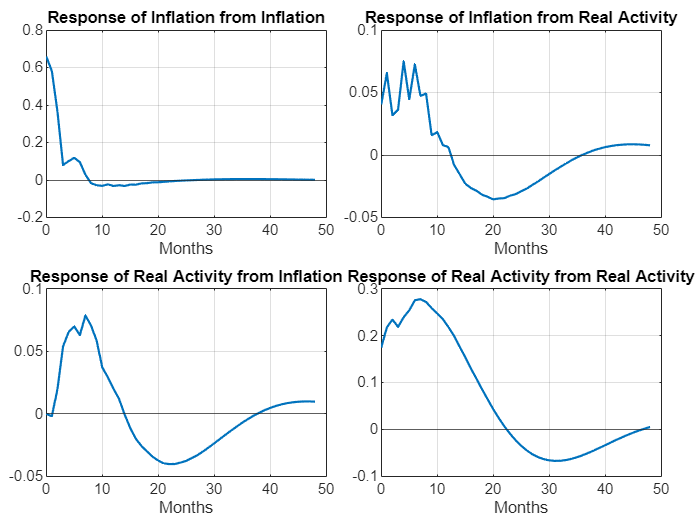

p = 8; % # of lags
Mdl  = varm(2,p);
Econ_Factor = zscore(Econ_Factor);
[EstMdl_F_activity_p1,~,~,info] = estimate(Mdl, Econ_Factor, 'Y0', Econ_Factor(1:p,:));  % provide presample

H = 48;
Phi_orth = var_irf_chol(EstMdl_F_activity_p1, H, Econ_Factor);   % F is your T×2 data matrix

tH = (0:H)';   % includes h=0

IR_Infl_from_Infl = squeeze(Phi_orth(2,2,:));
IR_Infl_from_RA   = squeeze(Phi_orth(2,1,:));
IR_RA_from_Infl   = squeeze(Phi_orth(1,2,:));
IR_RA_from_RA     = squeeze(Phi_orth(1,1,:));

tiledlayout(2,2,'Padding','compact','TileSpacing','compact');

nexttile; plot(tH, IR_Infl_from_Infl,'LineWidth',1.3); yline(0); grid on;
title('Response of Inflation from Inflation'); xlabel('Months');

nexttile; plot(tH, IR_Infl_from_RA,'LineWidth',1.3); yline(0); grid on;
title('Response of Inflation from Real Activity'); xlabel('Months');

nexttile; plot(tH, IR_RA_from_Infl,'LineWidth',1.3); yline(0); grid on;
title('Response of Real Activity from Inflation'); xlabel('Months');

nexttile; plot(tH, IR_RA_from_RA,'LineWidth',1.3); yline(0); grid on;
title('Response of Real Activity from Real Activity'); xlabel('Months');

## BVAR (8) Real Activity and Inflation

H = 48;   % horizons

% Minnesota hyperparameters
hyper = struct('lam1',0.30,'lam3',0.50,'lam4',0.10,'d',1,'priorRW',true);

out_bvar_ra = bvarp_minnesota_p8(Econ_Factor, 8, H, hyper);
% Coefficients
disp(out_bvar_ra.muM);        % intercepts

   1.0e-03 *

    0.0014
   -0.4328



disp(out_bvar_ra.PhiM);      % VAR(1) matrix


(:,:,1) =

    1.0722    0.0083
    0.0887    0.8301


(:,:,2) =

   -0.0298    0.0030
   -0.0122   -0.1652


(:,:,3) =

   -0.0213    0.0010
   -0.0012   -0.0490


(:,:,4) =

   -0.0125    0.0001
   -0.0063    0.0676


(:,:,5) =

   -0.0143   -0.0000
   -0.0280    0.0027


(:,:,6) =

   -0.0140   -0.0000
   -0.0091   -0.0119


(:,:,7) =

   -0.0127   -0.0000
   -0.0177   -0.0133


(:,:,8) =

   -0.0103   -0.0001
   -0.0112   -0.0078



disp(out_bvar_ra.SigmaM);     % innovations covariance

    0.0382    0.0101
    0.0101    0.5035



## Coefficients

head(out_bvar_ra.tables.eq1)   % coef/std/t/p de la ecuación 1 (inflación)

     Parametro       Coef       StdError       Tstat        PValue   
    ___________    _________    _________    _________    ___________

    {'const'  }    1.382e-06     0.001047    0.0013199        0.99895
    {'L1 infl'}       1.0722     0.028333       37.843    2.2504e-313
    {'L1 real'}    0.0082981    0.0067322       1.2326        0.21773
    {'L2 infl'}    -0.029849     0.025719      -1.1606        0.24582
    {'L2 real'}    0.0030438    0.0037549      0.81062        0.41758
    {'L3 infl'}    -0.021345     0.017957      -1.1887        0.23456
    {'L3 real'}    0.0010106    0.0025507       0.3962        0.69196
    {'L4 infl'}    -0.012457     0.013686     -0.91019        0.36272



head(out_bvar_ra.tables.eq2)   % coef/std/t/p de la ecuación 2 (actividad)

     Parametro        Coef        StdError      Tstat        PValue  
    ___________    ___________    ________    _________    __________

    {'const'  }    -0.00043276    0.013739    -0.031499       0.97487
    {'L1 infl'}       0.088735     0.15243      0.58215       0.56047
    {'L1 real'}        0.83006    0.059585       13.931    4.1242e-44
    {'L2 infl'}      -0.012221     0.16165    -0.075599       0.93974
    {'L2 real'}       -0.16519     0.06264      -2.6371     0.0083622
    {'L3 infl'}     -0.0012056      0.1151    -0.010475       0.99164
    {'L3 real'}      -0.049035    0.050345     -0.97399       0.33006
    {'L4 infl'}     -0.0063185    0.088933    -0.071048       0.94336



## Some Bayesian Checks

z = 1.96; 
ci_lo = out_bvar_ra.Bpost - z.*out_bvar_ra.seB 

ci_lo =    -0.0021   -0.0274
    1.0167   -0.2100
   -0.0049    0.7133
   -0.0803   -0.3291
   -0.0043   -0.2880
   -0.0565   -0.2268
   -0.0040   -0.1477
   -0.0393   -0.1806
   -0.0037   -0.0136
   -0.0359   -0.1695


ci_hi = out_bvar_ra.Bpost + z.*out_bvar_ra.seB

ci_hi =     0.0021    0.0265
    1.1277    0.3875
    0.0215    0.9469
    0.0206    0.3046
    0.0104   -0.0424
    0.0139    0.2244
    0.0060    0.0496
    0.0144    0.1680
    0.0039    0.1489
    0.0074    0.1135


ppos = 1 - 0.5*erfc( (out_bvar_ra.Bpost./out_bvar_ra.seB)/sqrt(2) ) % matriz (q x 2)

ppos =     0.5005    0.4874
    1.0000    0.7198
    0.8911    1.0000
    0.1229    0.4699
    0.7912    0.0042
    0.1173    0.4958
    0.6540    0.1650
    0.1814    0.4717
    0.5158    0.9486
    0.0980    0.3490


T1 = table(out_bvar_ra.paramNames, out_bvar_ra.Bpost(:,1), out_bvar_ra.seB(:,1), ci_lo(:,1), ci_hi(:,1), ppos(:,1), ...
  'VariableNames', {'Parametro','Coef','SE','CIlo','CIhi','PrPos'})

T1 = 17×6 table
     Parametro        Coef           SE           CIlo         CIhi        PrPos  
    ___________    ___________    _________    __________    _________    ________

    {'const'  }      1.382e-06     0.001047    -0.0020507    0.0020535     0.50053
    {'L1 infl'}         1.0722     0.028333        1.0167       1.1277           1
    {'L1 real'}      0.0082981    0.0067322    -0.0048971     0.021493     0.89114
    {'L2 infl'}      -0.029849     0.025719     -0.080258     0.020561     0.12291
    {'L2 real'}      0.0030438    0.0037549    -0.0043158     0.010403     0.79121
    {'L3 infl'}      -0.021345     0.017957     -0.056541      0.01385     0.11728
    {'L3 real'}      0.0010106    0.0025507    -0.0039888      0.00601     0.65402
    {'L4 infl'}      -0.012457  

T2 = table(out_bvar_ra.paramNames, out_bvar_ra.Bpost(:,2), out_bvar_ra.seB(:,2), ci_lo(:,2), ci_hi(:,2), ppos(:,2), ...
  'VariableNames', {'Parametro','Coef','SE','CIlo','CIhi','PrPos'})

T2 = 17×6 table
     Parametro        Coef           SE         CIlo         CIhi         PrPos  
    ___________    ___________    ________    _________    _________    _________

    {'const'  }    -0.00043276    0.013739    -0.027361     0.026495      0.48744
    {'L1 infl'}       0.088735     0.15243     -0.21002      0.38749      0.71977
    {'L1 real'}        0.83006    0.059585      0.71328      0.94685            1
    {'L2 infl'}      -0.012221     0.16165     -0.32906      0.30461      0.46987
    {'L2 real'}       -0.16519     0.06264     -0.28796    -0.042413    0.0041811
    {'L3 infl'}     -0.0012056      0.1151      -0.2268      0.22438      0.49582
    {'L3 real'}      -0.049035    0.050345     -0.14771     0.049641      0.16503
    {'L4 infl'}     -0.0063185    0.08893

## Plots BVAR

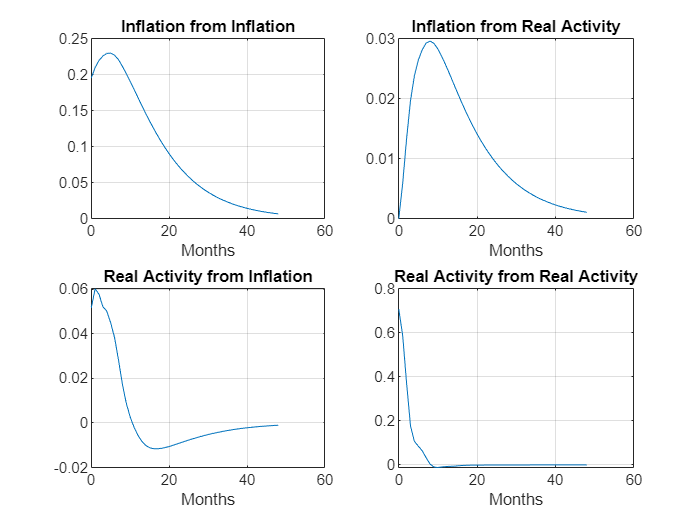

% Plot IRFs (Cholesky, infl first)
months = 0:H;
IRF = out_bvar_ra.IRF;   % 2 x 2 x (H+1)
figure;
subplot(2,2,1); plot(months, squeeze(IRF(1,1,:))); title('Inflation from Inflation');  xlabel('Months'); grid on;
subplot(2,2,2); plot(months, squeeze(IRF(1,2,:))); title('Inflation from Real Activity'); xlabel('Months'); grid on;
subplot(2,2,3); plot(months, squeeze(IRF(2,1,:))); title('Real Activity from Inflation'); xlabel('Months'); grid on;
subplot(2,2,4); plot(months, squeeze(IRF(2,2,:))); title('Real Activity from Real Activity'); xlabel('Months'); grid on;

## 5. Short Term Estimation

## 5.1. Taylor Rule

%% r is hort rate yield at 3m
r = yields_std(:,1)/100;

% Align & (optionally) standardize like A&P
valid = all(~isnan([r, Econ_Factor]), 2);
r = r(valid);
Econ_Factor = Econ_Factor(valid,:);
%%%Econ_Factor = zscore(Econ_Factor);   % 2nd standardization after PCA

%% ---- Eq. (3): contemporaneous Taylor rule ----
% r_t = a0 + d' f_t^o + v_t
X3 = [ones(size(r)), Econ_Factor];        % [1, infl, real]
b3 = X3 \ r;                             % OLS
v3 = r - X3*b3;                          % residuals  (≈ δ12' X_t^u)
R2_3 = 1 - (v3'*v3) / ((r-mean(r))'*(r-mean(r)));
rho_v3 = corr(v3(2:end), v3(1:end-1));   % AR(1) of residuals

fprintf('Eq(3) R^2 = %.3f, AR(1) resid = %.3f\n', R2_3, rho_v3);

Eq(3) R^2 = 0.207, AR(1) resid = 0.970


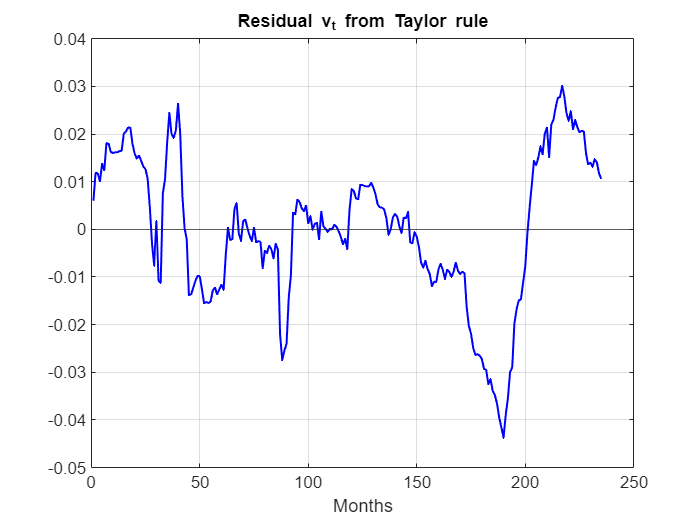


%% Plots like A&P Fig. 3
figure;
plot(v3,'b','LineWidth',1.2); yline(0); grid on;
title('Residual v_t from Taylor rule');
xlabel('Months');

## 5.2. Forward-Looking

%% ---- Eq. (4): forward-looking (lags proxy) ----
% r_t = b0 + b1' X_t^o + v_t,   X_t^o = [f_t, f_{t-1}, ..., f_{t-p}]
p  = 12;                                      % monthly
XL = lagmatrix(Econ_Factor, 0:p);              % T×(2*(p+1))
idx = all(~isnan(XL), 2);                     % drop initial p rows with NaNs
r4  = r(idx);
X4  = [ones(sum(idx),1), XL(idx,:)];

b4 = X4 \ r4;                                 % OLS
v4 = r4 - X4*b4;                              % residuals (≈ δ12' X_t^u)
R2_4 = 1 - (v4'*v4) / ((r4-mean(r4))'*(r4-mean(r4)));
rho_v4 = corr(v4(2:end), v4(1:end-1));       % AR(1) of residuals

fprintf('Eq(4) R^2 = %.3f, AR(1) resid = %.3f\n', R2_4, rho_v4);

Eq(4) R^2 = 0.503, AR(1) resid = 0.939


% Orthogonality
if size(X4,2) >= 3
    fprintf('corr(v4, infl_t) = %.3f, corr(v4, real_t) = %.3f\n', ...
        corr(v4, X4(:,2)), corr(v4, X4(:,3)));
end

corr(v4, infl_t) = 0.000, corr(v4, real_t) = 0.000


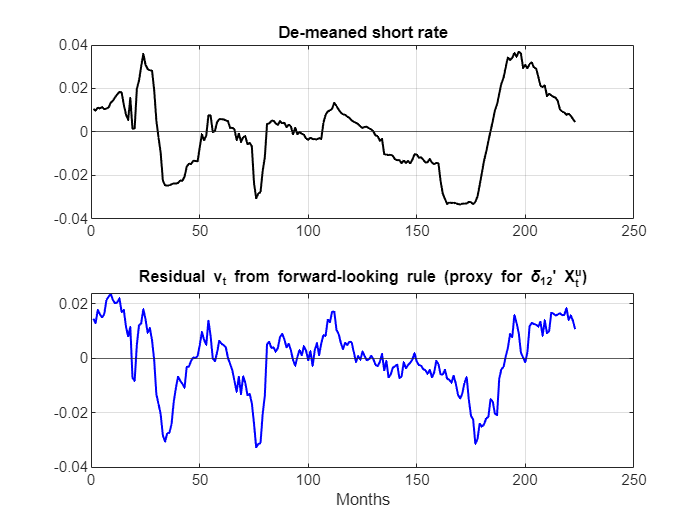


%% Plots like A&P Fig. 3
figure;
subplot(2,1,1);
plot(r4-mean(r4),'k','LineWidth',1.2); yline(0); grid on;
title('De-meaned short rate');
subplot(2,1,2);
plot(v4,'b','LineWidth',1.2); yline(0); grid on;
title('Residual v_t from forward-looking rule (proxy for \delta_{12}'' X_t^u)');
xlabel('Months');

## 5.3. Policy Inertia

## Interest-Rate Smoothing (Policy Inertia)

%rt=b_0+ρ*r_{t−1}+∑(β_{π,ℓ}*Infl_{t−ℓ}+β_{y,ℓ}*Real_{t−ℓ})+vt.
p   = 12;
XL  = lagmatrix(Econ_Factor,0:p);
rL1 = lagmatrix(r,1);
idx = all(~isnan([rL1 XL]),2);
y   = r(idx);
Xf  = [ones(sum(idx),1), rL1(idx), XL(idx,:)];
bf  = Xf \ y;
vf  = y - Xf*bf;
R2f = 1 - (vf'*vf) / ((y-mean(y))'*(y-mean(y)));
rhof= corr(vf(2:end), vf(1:end-1));
fprintf('Rule with r_{t-1}: R^2=%.3f, AR(1)(resid)=%.3f\n', R2f, rhof);

Rule with r_{t-1}: R^2=0.964, AR(1)(resid)=0.263


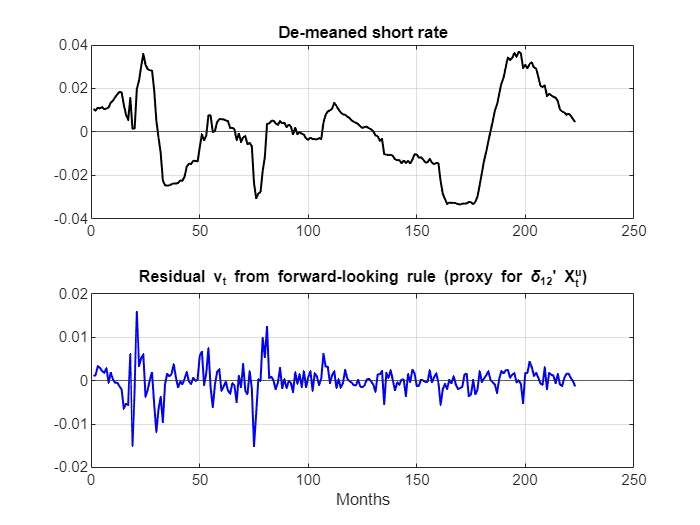

%% Plots like A&P Fig. 3
figure;
subplot(2,1,1);
plot(y-mean(y),'k','LineWidth',1.2); yline(0); grid on;
title('De-meaned short rate');
subplot(2,1,2);
plot(vf,'b','LineWidth',1.2); yline(0); grid on;
title('Residual v_t from forward-looking rule (proxy for \delta_{12}'' X_t^u)');
xlabel('Months');

## 5.4. Long Run Response (Policy Intertia)

b0   = bf(1);
rho  = bf(2);
Bmat = reshape(bf(3:end), 2, [])';     % rows: lag 0..p, cols: [infl, real]

beta_pi_sum  = sum(Bmat(:,1));         % sum of inflation lags
beta_real_sum= sum(Bmat(:,2));         % sum of real-activity lags

fprintf('b0=%.6f, rho=%.4f\n', b0, rho);

b0=0.001596, rho=0.9545


fprintf('Sum of infl lags=%.6f, Sum of real lags=%.6f\n', beta_pi_sum, beta_real_sum);

Sum of infl lags=0.001103, Sum of real lags=0.001034



LR_infl = beta_pi_sum  / (1 - rho);
LR_real = beta_real_sum/ (1 - rho);
fprintf('Long-run infl response=%.3f, long-run real response=%.3f\n', LR_infl, LR_real);

Long-run infl response=0.024, long-run real response=0.023


## 5.5. Policy Inertia Analysis

Tn   = size(Xf,1);
k    = size(Xf,2);
sigma2 = (vf'*vf) / (Tn - k);         % residual variance

% Var(b) = sigma2 * (X'X)^(-1) without inv():
XtX  = Xf' * Xf;
V    = sigma2 * (XtX \ eye(k));       % (X'X)\I  == (X'X)^(-1)
se   = sqrt(diag(V));                 % standard errors

% t-stats and p-values (two-sided)
tstat = bf ./ se;
pval  = 2*(1 - tcdf(abs(tstat), Tn - k));

% Pretty table with names
p = 12;
lagNames = compose('lag%02d', 0:p)';
rowNames = [{'const'}; {'r_{t-1}'}; strcat('infl_',lagNames); strcat('real_',lagNames)];
coefTbl  = table(bf, se, tstat, pval, 'VariableNames', {'Estimate','StdErr','tStat','pValue'}, ...
                 'RowNames', rowNames);

disp(coefTbl)           % <- p-values are in the pValue column

                   Estimate        StdErr       tStat       pValue 
                  ___________    __________    ________    ________

    const           0.0015962    0.00072123      2.2131    0.028048
    r_{t-1}           0.95454       0.01899      50.266           0
    infl_lag00      0.0010142     0.0014148      0.7169      0.4743
    infl_lag01     0.00067128    0.00036759      1.8262    0.069355
    infl_lag02      0.0029703     0.0022204      1.3377     0.18254
    infl_lag03     6.7133e-05    0.00047836     0.14034     0.88854
    infl_lag04     -0.0026697     0.0022321     -1.1961     0.23312
    infl_lag05    -0.00079155    0.00048471      -1.633     0.10408
    infl_lag06     0.00043341 

## 6. Estimation Macro VAR(8) with Short Term Est with No Lags

% Inputs:
Curve_mo  = yields_std/(12*100); % [T x J] yields (annualized %); first column must be 1m.
nList = [3 12 24 84 108 120];
floors = [18 14 18 35 40 45]; % bp/year (tune if needed)
lam_sr = 0; 

var_p8_2stp = ap_two_step_var_p8(Curve_mo, Econ_Factor, nList, floors, lam_sr);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          34      1.97531e+06                      1.82e+08
     1         204          1068.04    1.99062e-10       2.92e+06  
     2         238         -1886.41              1       2.18e+06  
     3         272         -6729.87              1       6.43e+05  
     4         306         -7277.85              1       2.35e+05  
     5         340         -7366.52              1       4.75e+04  
     6         374         -7369.54              1       1.53e+04  
     7         442         -7369.54       0.225697       1.51e+04  
     8         476         -7369.62              1       1.32e+04  
     9         510          -7369.9              1       1.52e+04  
    10         544         -7371.54              1       3.45e+04  
    11         578         -7377.14              1       6.98e+04  
    12         748         -7781.12         3.649

## 4.2. Latent Factors

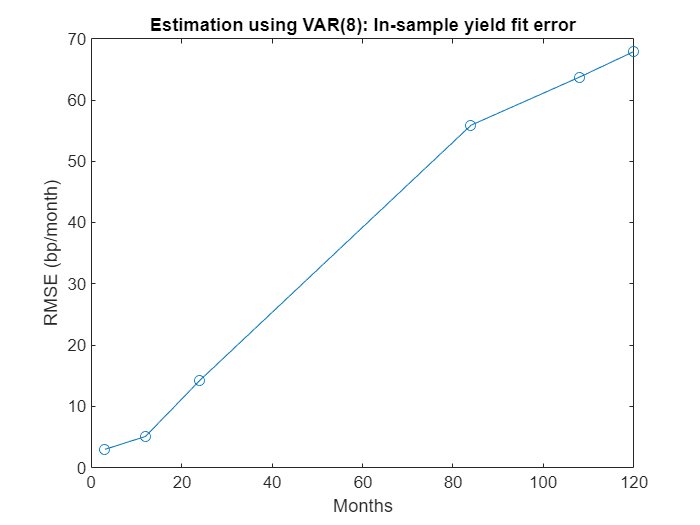

S = smooth_latent(var_p8_2stp, Curve_mo, Econ_Factor, nList);
err_VAR = Curve_mo(8+1:end,:) - S.Yhat;                % pricing errors (monthly decimals)
rmse_VAR_bp  = sqrt(mean(err_VAR.^2,1))  * 120000;
% quick plot
figure;
plot(nList, rmse_VAR_bp,'-o'); xlabel('Months'); ylabel('RMSE (bp/month)');
title('Estimation using VAR(8): In-sample yield fit error');

## 4.3.Loadings por vencimiento (intercepto, macro y latentes)

J   = numel(nList); 
nList_col = nList(:);
% Ko = dimensión en forma compañera (= K1 * p)
Ko = size(var_p8_2stp.step1.fixed.Phi_o, 1);
K1  = size(Econ_Factor,2); 
p   = Ko / K1;
assert(mod(p,1)==0, 'Orden p no entero: revisa dimensiones.');

A_n   = S.misc.A ./ nList_col;          % Jx1  intercepto por n
BLat_n = S.misc.B_L ./ nList_col;       % Jx3  loadings latentes por n

% Macro “corriente” (las PRIMERAS K1 columnas del estado apilado):
BMac_curr_n = S.misc.B_Maug(:,1:K1) ./ nList_col;       % JxK1

% Macro rezagos (para ver efecto de cada lag en el pricing bajo Q):
BMac_lag_n  = cell(p-1,1);
for l = 2:p
    cols = ( (l-1)*K1 + (1:K1) );
    BMac_lag_n{l-1} = S.misc.B_Maug(:,cols) ./ nList_col;  % JxK1
end


## 4.4. Descomposición del yield fitted en un tiempo t

% Asegura el índice dentro de [1, T-p]
T    = size(Curve_mo,1);
t_in = min(max(1, 100), T-p);
t0   = t_in + p;

%% --- Construye el estado macro apilado Xo_t = [M_t; M_{t-1}; ... ; M_{t-p+1}]
Xo_t = zeros(Ko,1);
for l = 0:p-1
    Xo_t(l*K1+(1:K1)) = Econ_Factor(t0-l,:).';
end

%% --- Loadings por n (usa bsxfun por compatibilidad)
A_n     = bsxfun(@rdivide, S.misc.A,     nList_col);   % Jx1
BLat_n  = bsxfun(@rdivide, S.misc.B_L,   nList_col);   % Jx3
BMac_n  = bsxfun(@rdivide, S.misc.B_Maug,nList_col);   % JxKo

%% --- Descomposición en el tiempo t_in
interc = A_n;                          % Jx1
macro  = BMac_n * Xo_t;                % Jx1  (suma de todos los lags)
latent = BLat_n * S.smooth_latent(:,t_in);  % Jx1

yhat_t = interc + macro + latent;      % Jx1

%% --- Aporte por lag (columnas = lags 1..p)
macro_parts = zeros(J,p);
for l = 1:p
    cols = (l-1)*K1 + (1:K1);
    macro_parts(:,l) = BMac_n(:,cols) * Xo_t(cols);  % Jx1
end
% sum(macro_parts,2) == macro

%% --- Aporte por cada factor latente (columnas = 3 latentes)
s_t = S.smooth_latent(:,t_in).';       % 1x3
latent_parts = bsxfun(@times, BLat_n, s_t);  % Jx3
% sum(latent_parts,2) == latent


## 4.5. Curvas de loadings

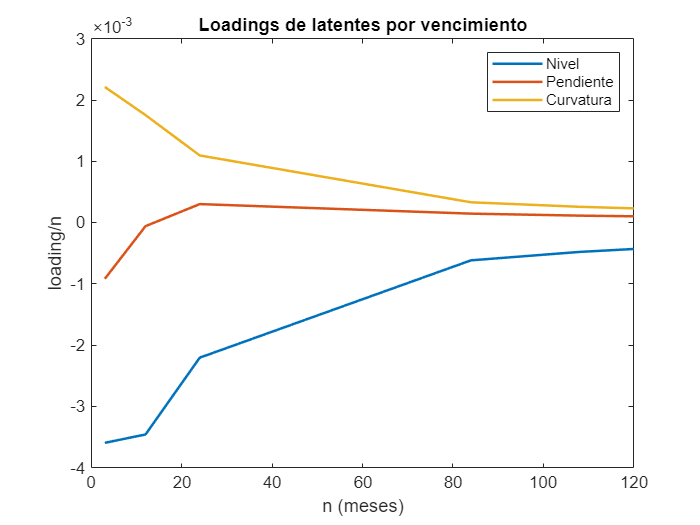

% Loadings latentes a través de la curva (por vencimiento):
BLat_n   = S.misc.B_L ./ nList_col;            % Jx3
BMac0_n  = S.misc.B_Maug(:,1:K1) ./ nList_col; % JxK1 (macro corriente)

% Ejemplo: gráfico rápido en MATLAB
figure; plot(nList_col, BLat_n, 'LineWidth',1.5); legend('Nivel','Pendiente','Curvatura'); xlabel('n (meses)'); ylabel('loading/n');
title('Loadings de latentes por vencimiento');

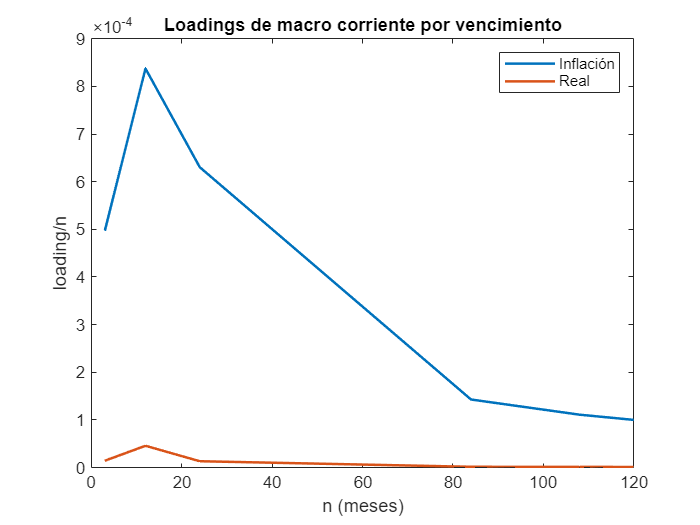


figure; plot(nList_col, BMac0_n, 'LineWidth',1.5); legend('Inflación','Real'); xlabel('n (meses)'); ylabel('loading/n');
title('Loadings de macro corriente por vencimiento');

## 5. Yield Curve Estimation with BVAR (8) on Econ Indicators

## 5.1. Step 1 and 2 - BVAR (8)

% Minnesota hyperparameters
hyper = struct('lam1',0.60, ...    % overall tightness
               'lam3',0.60,  ...    % cross-variable shrink
               'lam4',0.10, ...    % intercept scale
               'd',1.0,     ...    % lag decay
               'priorRW',true, ...
               'lam_sr',2);        % ridge for short rate regression

floors = [15 15 15 18 22 25];      % bp/year, one per maturity in nList

out_bvar = ap_two_step_bvar_p8(Curve_mo, Econ_Factor, nList, hyper, floors);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          34      6.67597e+07                      3.42e+09
     1         102       1.7798e+07    2.92615e-11       4.24e+09  
     2         170      1.58833e+07        0.33421       3.06e+09  
     3         204      2.63144e+06              1       1.26e+08  
     4         238      1.82037e+06              1       8.47e+07  
     5         272           501763              1       4.05e+07  
     6         306           172676              1       2.24e+07  
     7         340          41322.9              1       1.04e+07  
     8         374          7603.89              1        4.3e+06  
     9         408          1141.36              1       2.39e+06  
    10         442          511.949              1       1.84e+06  
    11         476          368.957              1       1.98e+06  
    12         510          71.7919              

## Eigenvalores

% RMSE
out_bvar.fit.rmse_bp

ans =    16.0326   55.1187   68.1104  109.8257   23.1321  116.2965


eig(out_bvar.step2.params.RHO)           % should be < 1 in modulus

ans =     0.9498
    0.9008
    0.9498


out_bvar.fit.meas_std_bp

ans =    21.2134   21.2147   21.2151   25.4561   31.1141   35.3583


## 5.2. RMSE BVAR

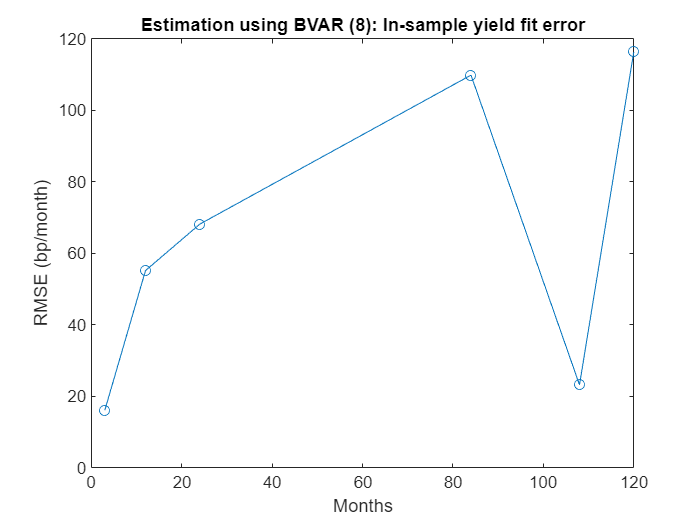

err_BVAR = Curve_mo(8+1:end,:) - out_bvar.fit.Yhat;              % monthly decimals
rmse_BVAR_bp = sqrt(mean(err_BVAR.^2,1)) * 120000;
figure;
plot(nList, rmse_BVAR_bp,'-o'); xlabel('Months'); ylabel('RMSE (bp/month)');
title('Estimation using BVAR (8): In-sample yield fit error');

p = out_bvar.step2.params;
meas_std_bp_ann = sqrt(exp(p.logRy_diag)) * 1200

meas_std_bp_ann =     0.1500
    0.1500
    0.1500
    0.1800
    0.2200
    0.2500


## Testing VAR (8) and BVAR (8)

SaV = summarize(var_p8_2stp,  nList);
SaB = summarize(out_bvar, nList);
fprintf('AIC (VAR,BVAR):  %.1f   %.1f\n', SaV.AIC, SaB.AIC);

AIC (VAR,BVAR):  -16053.0   -3640.3


fprintf('BIC (VAR,BVAR):  %.1f   %.1f\n\n', SaV.BIC, SaB.BIC);

BIC (VAR,BVAR):  -15939.9   -3527.3



## BVAR (1)

hyper = struct();
hyper.lam1 = 0.25; hyper.lam3 = 0.50; hyper.lam4 = 0.10; hyper.d = 1; hyper.priorRW = true;
hyper.lam_sr = 0;   

% Minnesota hyperparameters
%hyper = struct('lam1',0.60, ...    % overall tightness
%               'lam3',0.60,  ...    % cross-variable shrink
%               'lam4',0.10, ...    % intercept scale
%               'd',1.0,     ...    % lag decay
%               'priorRW',true, ...
%               'lam_sr',2);        % ridge for short rate regression

floors = [15 15 15 18 22 25];      % bp/year, one per maturity in nList

out_bvar = ap_two_step_bvar(Curve_mo, Econ_Factor, nList, hyper, floors);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          34      2.16034e+08                      2.05e+10
     1         170      3.77999e+07    6.10831e-12       7.93e+09  
     2         238          37898.2       0.398297       2.97e+07  
     3         306          11385.9             10       1.22e+07  
     4         340          1694.23              1       4.92e+06  
     5         374          -1780.5              1       3.75e+06  
     6         408         -3120.42              1       3.14e+06  
     7         442         -3384.48              1       2.95e+06  
     8         476         -3517.82              1       2.85e+06  
     9         510         -3878.52              1       3.13e+06  
    10         544         -4624.47              1       3.68e+06  
    11         578          -6039.8              1       3.68e+06  
    12         612         -7595.76              

## Eigenvalues

% RMSE
out_bvar.fit.rmse_bp

ans =     6.3934   16.2854   21.1049   12.9223   25.6993   33.8062


eig(out_bvar.step2.params.RHO) 

ans =     0.9698
    0.9003
    0.9603


out_bvar.fit.meas_std_bp

ans =    21.2133   21.2141   21.2143   25.4559   31.1136   35.3570


## RSME

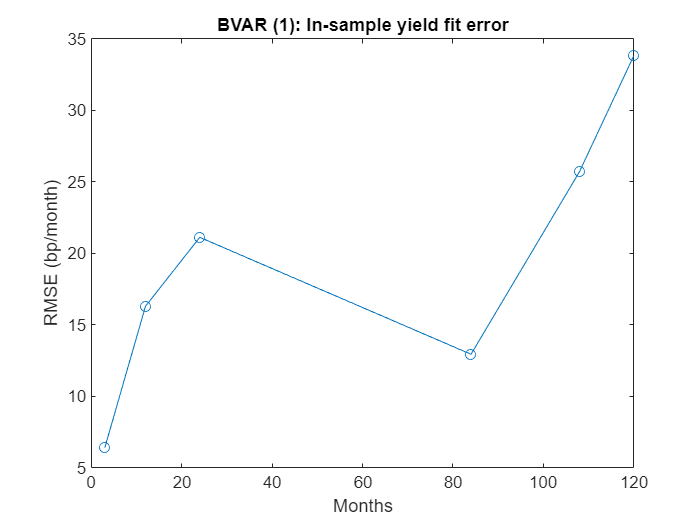

err_BVAR = Curve_mo - out_bvar.fit.Yhat;              % monthly decimals
rmse_BVAR_bp = sqrt(mean(err_BVAR.^2,1)) * 120000;
figure;
plot(nList, rmse_BVAR_bp,'-o'); xlabel('Months'); ylabel('RMSE (bp/month)');
title('BVAR (1): In-sample yield fit error');

p = out_bvar.step2.params;
meas_std_bp_ann = sqrt(exp(p.logRy_diag)) * 1200

meas_std_bp_ann =     0.1500
    0.1500
    0.1500
    0.1800
    0.2200
    0.2500


## Testing VAR (8) and BVAR (1)

SaV = summarize(var_p8_2stp,  nList);
SaB = summarize(out_bvar, nList);
fprintf('AIC (VAR,BVAR):  %.1f   %.1f\n', SaV.AIC, SaB.AIC);

AIC (VAR,BVAR):  -16053.0   -17588.2


fprintf('BIC (VAR,BVAR):  %.1f   %.1f\n\n', SaV.BIC, SaB.BIC);

BIC (VAR,BVAR):  -15939.9   -17474.1



## Getting the Loadings

% 1) Loadings consistent with your estimated model
L = get_ATSM_loadings_bvar1(out_bvar.step1.fixed, out_bvar.step2.params, out_bvar.meta.nList);

% 2) Quick look
Tload = make_loading_table_bvar1(L);
head(Tload)

    nMonths    A_over_n       BM_inf        BM_act         BL_1           BL_2          BL_3    
    _______    _________    __________    __________    ___________    __________    ___________

        3      0.0020501    0.00042696    2.4957e-05     0.00015111     0.0052501     -0.0020258
       12       0.003396    0.00052775    2.4932e-05    -0.00017726     0.0043008      -0.001909
       24      0.0042556    0.00048154    2.1157e-05    -0.00038507     0.0026433     -0.0010871
       84      0.0052339    0.00027823    1.1629e-05    -0.00023848    0.00081411    -0.00014869
      108      0.0053352    0.00023101    9.6249e-06    -0.00018621    0.00063441    -0.00011306
      120       0.005371     0.0002121    8.8289e-06    -0.00016761    0.00057108 

## Initial Plotting

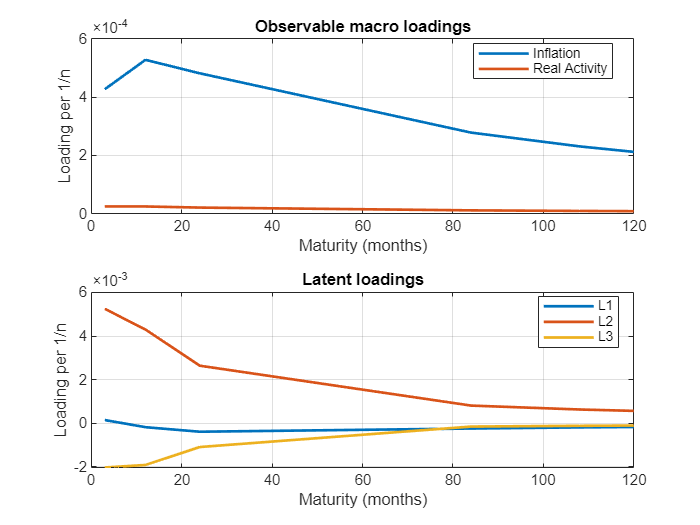

% 3) Plots: observable (macro) vs latent loadings 
plot_loading_curves_bvar1(L);

## Contribution by Factor

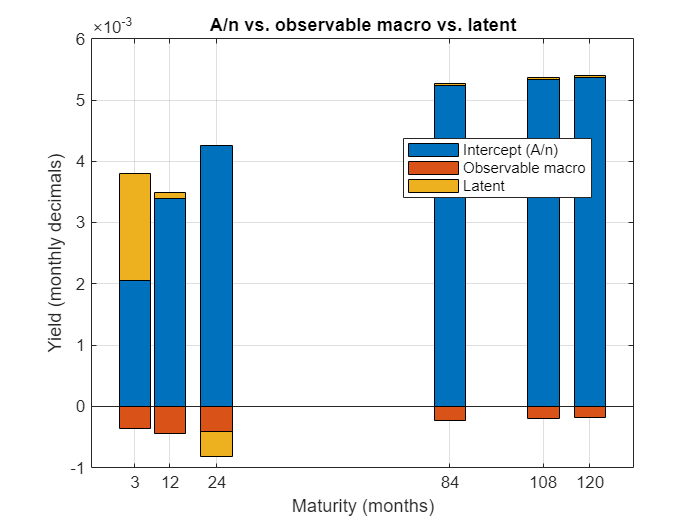

% 4) Cross-sectional contribution at a chosen t (1..T)
tPlot = size(out_bvar.fit.Yhat,1);
D = yield_contrib_at_t_bvar1(tPlot, L, Econ_Factor, out_bvar.latent.smooth);
plot_contrib_cross_section_bvar1(D);

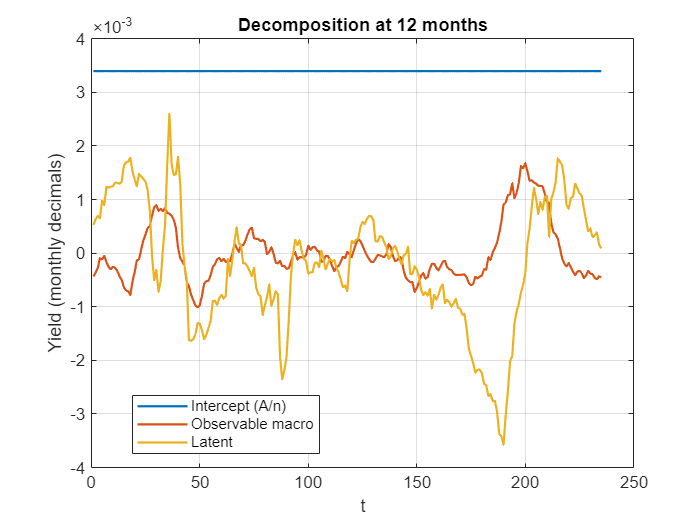

% 5) Time-series contributions for a chosen tenor (e.g., 120m)
plot_contrib_timeseries_bvar1(12, L, Econ_Factor, out_bvar.latent.smooth);

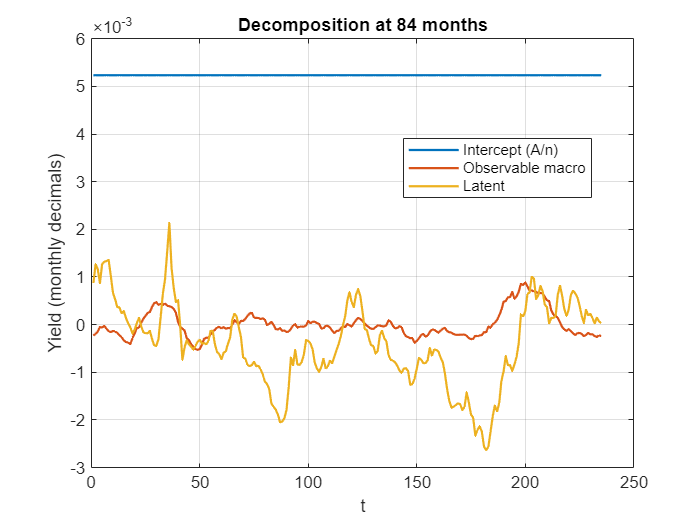

plot_contrib_timeseries_bvar1(84, L, Econ_Factor, out_bvar.latent.smooth);

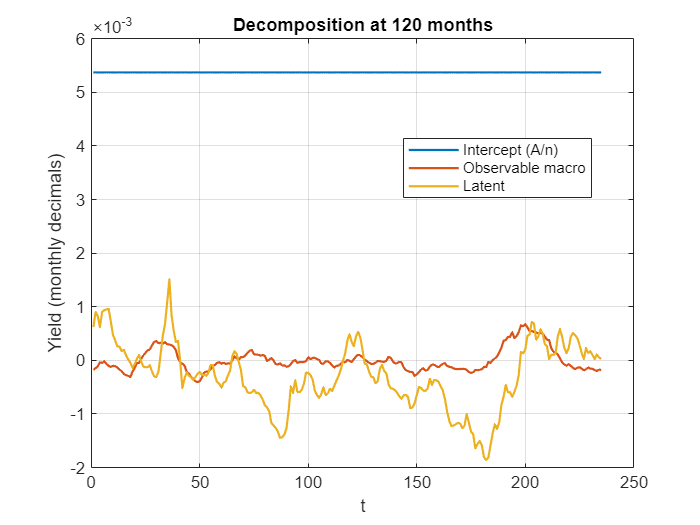

plot_contrib_timeseries_bvar1(120, L, Econ_Factor, out_bvar.latent.smooth);

## Variance Decomposition

% 6) Variance decomposition (long-run, unconditional)
VD = variance_decomp_bvar1(out_bvar.step1.fixed, out_bvar.step2.params, out_bvar.meta.nList, out_bvar.meta.floors_bp);
VD.table(1:min(10,height(VD.table)),:)   % peek

ans = 6×8 table
    nMonths    sd_total_bp    sd_macro_bp    sd_latent_bp    sd_meas_bp    share_macro    share_latent    share_meas
    _______    ___________    ___________    ____________    __________    ___________    ____________    __________

        3        1706.2         52.246          1705.2         21.213       0.0009377       0.99891       0.00015459
       12        1483.1         64.486          1481.6         21.214       0.0018905        0.9979        0.0002046
       24        906.26         58.816           904.1         21.214        0.004212       0.99524       0.00054796
       84         252.5         33.975          248.91         25.456        0.018104       0.97173         0.010164
      108

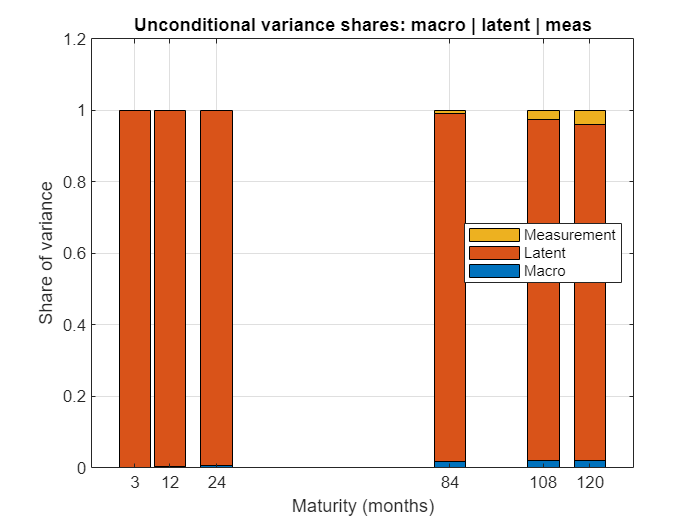

plot_variance_decomp_bvar1(VD);

## Forecast Dev

FE = fevd_yields_bvar1(out_bvar, [3 12 60 Inf], true, false);
disp(FE.table(FE.table.nMonths==3,:))      % block for 3-month yield

    nMonths     h      sh_macro     sh_latent     sh_meas  
    _______    ___    __________    _________    __________

       3         3    0.00030085      0.9993     0.00039813
       3        12    0.00048682     0.99932     0.00019596
       3        60    0.00088533     0.99896     0.00015741
       3       Inf     0.0009377     0.99891     0.00015459



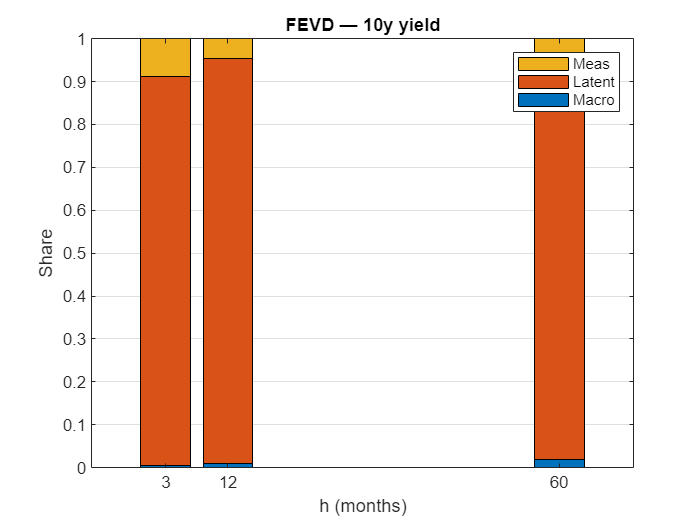


% Simple plot for, say, 10y:
j10 = find(out_bvar.meta.nList==120,1);         % adjust to your 10y code
bar(FE.horizons, [FE.share_macro(j10,:).', FE.share_latent(j10,:).', FE.share_meas(j10,:).'], 'stacked');
grid on; xlabel('h (months)'); ylabel('Share'); title('FEVD — 10y yield'); legend('Macro','Latent','Meas');

## Plot for 1y, 7y, 10y

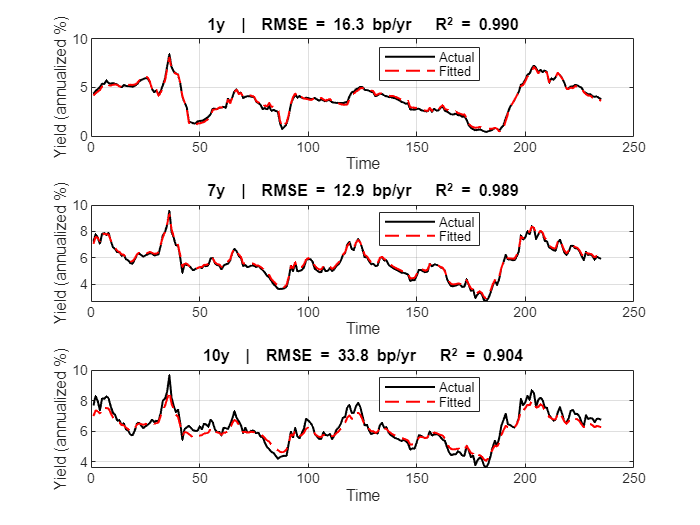

Ysel   = Curve_mo(:, [2 4 6]);       % T x 3 actuals
Yhsel  = out_bvar.fit.Yhat(:,  [2 4 6]);   % T x 3 fitted
rmseBP = out_bvar.fit.rmse_bp([2 4 6]);    % 1 x 3 corresponding RMSE bp/yr

% Choose plotting units
ann_pct = true;   % true = plot in annualized percent; false = monthly decimals

if ann_pct
    scale = 1200;                              % 12 * 100
    ylab  = 'Yield (annualized %)';
else
    scale = 1;                                 % no scaling
    ylab  = 'Yield (monthly decimals)';
end

Tenors_tt = [1 7 10];
rmseBP = out_bvar.fit.rmse_bp([2 4 6]);  

t = (1:size(Ysel,1))';
tiledlayout(3,1,'TileSpacing','compact');
for j = 1:3
    nexttile;
    plot(t, scale*Ysel(:,j),  'k-', 'LineWidth', 1.2); hold on;
    plot(t, scale*Yhsel(:,j), 'r--','LineWidth', 1.2);

    y  = Ysel(:,j); yh = Yhsel(:,j);
    r2 = 1 - sum((y - yh).^2) / sum((y - mean(y)).^2);

    title(sprintf('%dy  |  RMSE = %.1f bp/yr   R^2 = %.3f',Tenors_tt(j),rmseBP(j),r2));
    xlabel('Time'); ylabel(ylab); grid on;
    legend('Actual','Fitted','Location','best');
end

## BVAR(1) Variance Adjustment New Estimation

hyper = struct();
hyper.lam1 = 0.25; hyper.lam3 = 0.50; hyper.lam4 = 0.10; hyper.d = 1; hyper.priorRW = true;
hyper.lam_sr = 0;                            % ridge on short-rate regression (0 = none)

% Gentle prior on Q_L (helps FEVD not be 100% latent). Tune if needed:
hyper.qL_mean   = [0.01 0.01 0.01];          % prior mean for diag(Q_L)
hyper.qL_sd_log = 0.7;                        % prior sd on log scale
hyper.qL_weight = 2.0;                        % prior weight (×T)
hyper.lam1LL_ridge = 0.0;                     % tiny ridge on lambda1_LL (0 = off)

%Previous considered prior
%hyper = struct('lam1',0.60, ...    % overall tightness
%               'lam3',0.60,  ...    % cross-variable shrink
%               'lam4',0.10, ...    % intercept scale
%               'd',1.0,     ...    % lag decay
%               'priorRW',true, ...
%               'lam_sr',2);  

floors = [15 15 15 18 22 25];      % bp/year, one per maturity in nList

out_bvar_vadj = ap_two_step_bvar_variance_adj(Curve_mo, Econ_Factor, nList, hyper, floors);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          37           441062                      5.82e+07
     1         222           365877    2.13394e-10       2.13e+07  
     2         259           239451              1       1.26e+07  
     3         296           140991              1       7.83e+06  
     4         333          51862.2              1       3.49e+06  
     5         370          16561.7              1       1.63e+06  
     6         407          571.005              1       8.32e+05  
     7         444         -5824.19              1       3.87e+05  
     8         481          -8078.8              1       1.46e+05  
     9         518         -8544.47              1        4.1e+04  
    10         555         -8598.77              1       2.29e+04  
    11         592          -8603.4              1       2.35e+04  
    12         629         -8603.78              

## RMSE

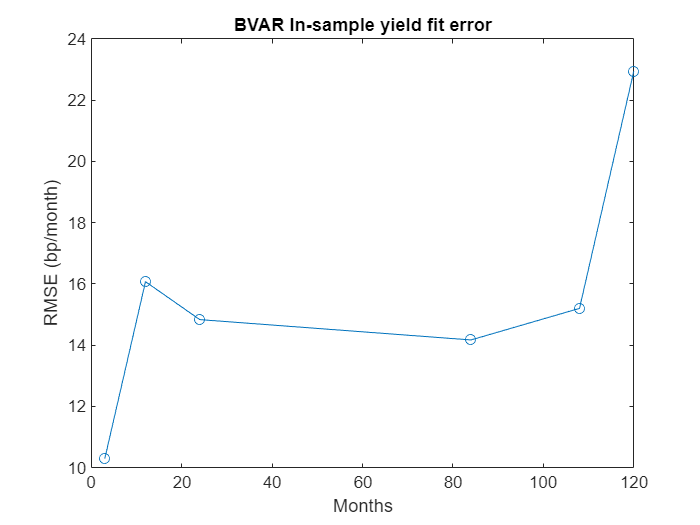

err_BVAR_vadj = Curve_mo - out_bvar_vadj.fit.Yhat;              % monthly decimals
rmse_BVAR_bp_vadj = sqrt(mean(err_BVAR_vadj.^2,1)) * 120000;
figure;
plot(nList, rmse_BVAR_bp_vadj,'-o'); xlabel('Months'); ylabel('RMSE (bp/month)');
title('BVAR In-sample yield fit error');

## Testing VAR (8) and BVAR (1)

SaV = summarize(var_p8_2stp,  nList);
SaB = summarize(out_bvar_vadj, nList);
fprintf('AIC (VAR,BVAR):  %.1f   %.1f\n', SaV.AIC, SaB.AIC);

AIC (VAR,BVAR):  -16053.0   -18491.1


fprintf('BIC (VAR,BVAR):  %.1f   %.1f\n\n', SaV.BIC, SaB.BIC);

BIC (VAR,BVAR):  -15939.9   -18376.9



## Forecast Dev

FE = fevd_yields_bvar1(out_bvar_vadj, [3 12 60 Inf], true, false);
disp(FE.table(FE.table.nMonths==3,:))      % block for 3-month yield

    nMonths     h      sh_macro     sh_latent     sh_meas  
    _______    ___    __________    _________    __________

       3         3    7.9933e-05     0.99981     0.00010575
       3        12    9.8743e-05     0.99986     3.9738e-05
       3        60    0.00011986     0.99986     2.1305e-05
       3       Inf    0.00012128     0.99986      1.999e-05



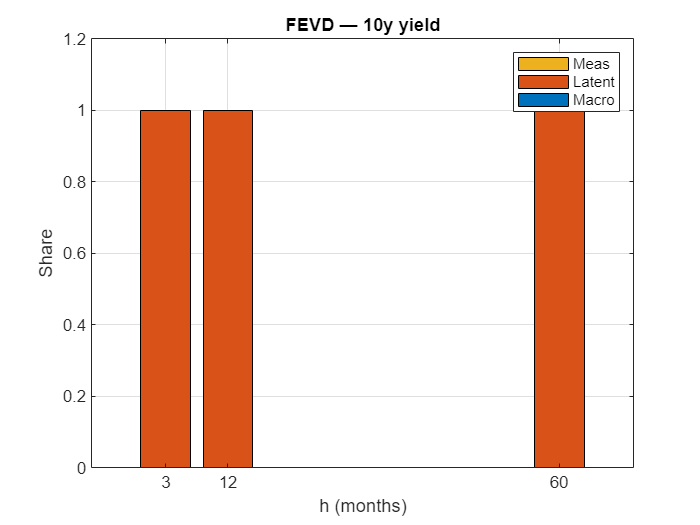

% Simple plot for, say, 10y:
j10 = find(out_bvar_vadj.meta.nList==24,1);         % adjust to your 10y code
bar(FE.horizons, [FE.share_macro(j10,:).', FE.share_latent(j10,:).', FE.share_meas(j10,:).'], 'stacked');
grid on; xlabel('h (months)'); ylabel('Share'); title('FEVD — 10y yield'); legend('Macro','Latent','Meas');